# 多元回归模型

% 数据输入
x1 = [5.5 2.5 8.0 3.0 3.0 2.9 8.0 9.0 4.0 6.5 5.5 5.0 6.0 5.0 3.5 8.0 6.0 4.0 7.5 7.0]';
x2 = [31 55 67 50 38 71 30 56 42 73 60 44 50 39 55 70 40 50 62 59]';
x3 = [10 8 12 7 8 12 12 5 8 5 11 12 6 10 10 6 11 11 9 9]';
x4 = [8 6 9 16 15 17 8 10 4 16 7 12 6 4 4 14 6 8 13 11]';
y  = [79.3 200.1 163.2 200.1 146.0 177.7 30.9 291.9 160.0 339.4 159.6 86.3 237.5 107.2 155.0 201.4 100.2 135.8 223.3 195.0]';
X  = [ones(size(x1)),x1,x2,x3,x4];

[b, bint, r, rint, stats] = regress(y,X)

b =   191.9158
   -0.7719
    3.1725
  -19.6811
   -0.4501


bint =   103.1071  280.7245
   -7.1445    5.6007
    2.0640    4.2809
  -25.1651  -14.1972
   -3.7284    2.8283


r =    -6.3045
   -4.2215
    5.1293
   -3.1536
    0.0469
    6.6035
  -10.2401
   32.1803
   -2.8219
   26.5194


rint =   -56.5085   43.8995
  -51.7960   43.3530
  -40.4734   50.7319
  -49.7055   43.3983
  -44.3616   44.4554
  -33.2319   46.4388
  -53.1505   32.6704
   -9.9247   74.2853
  -52.7697   47.1259
  -17.9495   70.9883


stats =     0.9034   35.0509    0.0000  644.6510


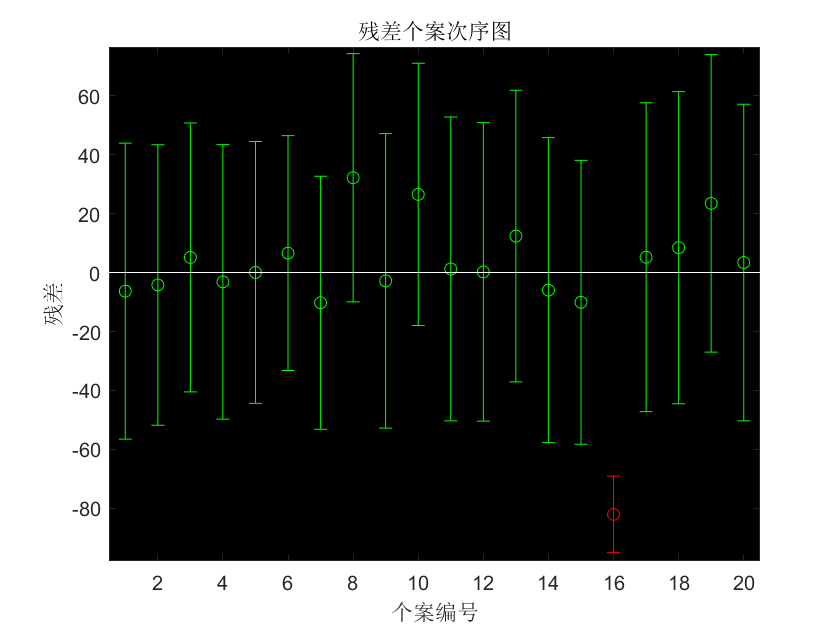


rcoplot(r, rint)

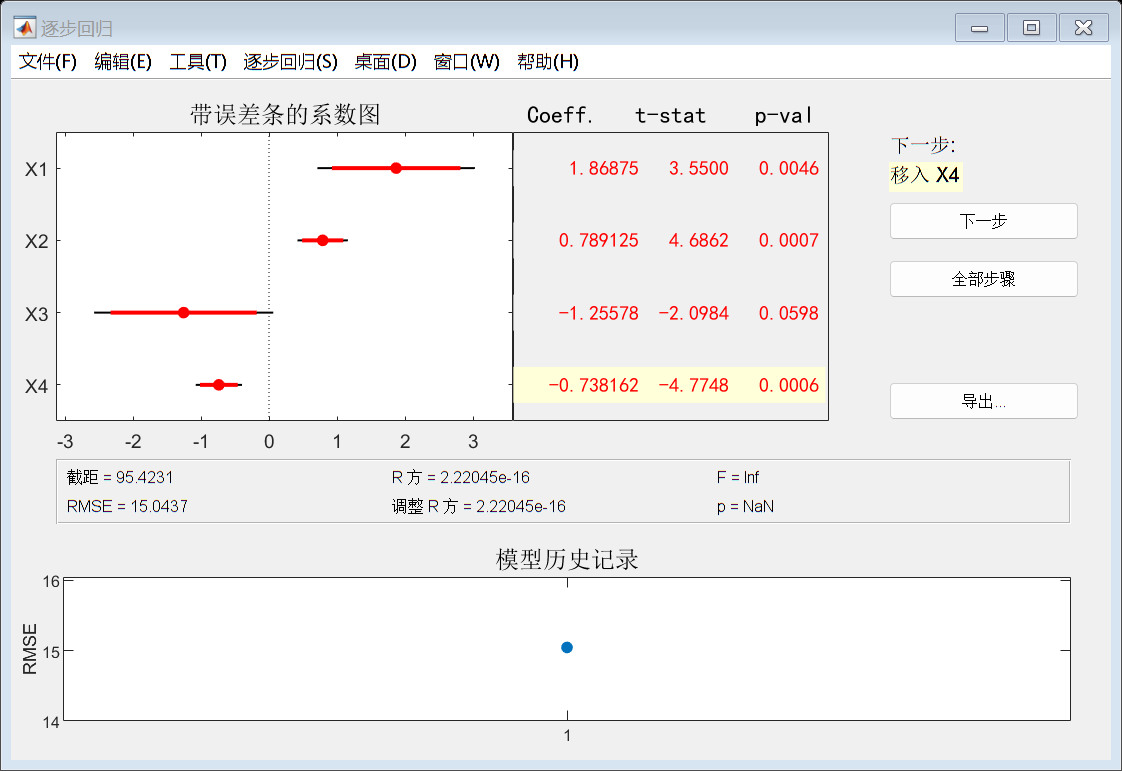


% 数据输入
x1 = [7 1 11 11 7 11 3 1 2 21 1 11 10]';
x2 = [26 29 56 31 52 55 71 31 54 47 40 66 68]';
x3 = [6 15 8 8 6 9 17 22 18 4 23 9 8]';
x4 = [60 52 20 47 33 22 6 44 22 26 34 12 12]';
y  = [78.5 74.3 104.3 87.6 95.9 109.2 102.7 72.5 93.1 115.9 83.8 113.3 109.4]';
x  = [x1 x2 x3 x4];

stepwise(x,y) % 使用逐步回归分析方法， 选取最佳模型


% 线性回归
X = [ones(13, 1) x1 x2];
b = regress(y, X)

b =    52.5773
    1.4683
    0.6623



% 作图
x1 = -10:0.1:10;
x2 = -10:0.1:10;

% 计算对应的因变量值
[X1, X2] = meshgrid(x1, x2) % 创建网络点坐标矩阵

X1 =   -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000
  -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -

X2 =   -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000
   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -9.9000   -

Z = 52.5773 + 1.4683*X1 + 0.6623*X2 % 计算对应的因变量值

Z =    31.2713   31.4181   31.5650   31.7118   31.8586   32.0055   32.1523   32.2991   32.4459   32.5928   32.7396   32.8864   33.0333   33.1801   33.3269   33.4738   33.6206   33.7674   33.9142   34.0611   34.2079   34.3547   34.5016   34.6484   34.7952   34.9421   35.0889   35.2357   35.3825   35.5294   35.6762   35.8230   35.9699   36.1167   36.2635   36.4104   36.5572   36.7040   36.8508   36.9977   37.1445   37.2913   37.4382   37.5850   37.7318   37.8787   38.0255   38.1723   38.3191   38.4660
   31.3375   31.4844   31.6312   31.7780   31.9248   32.0717   32.2185   32.3653   32.5122   32.6590   32.8058   32.9527   33.0995   33.2463   33.3932   33.5400   33.6868   33.8336   33.9805   34.1273   34.2741   34.4210   34.5678   34.7146   34.8615   35.0083   35.1551   35.3019   35.4488   35.5956   35.7424   35.8893   36.0361   36.1829   36.3298   36.4766   36.6234   36.7702   36.9171   37.0639   37.2107   37.3576   37.5044   37.6512   37.7981   37.9449   38.0917   38.2385   38.3854   38

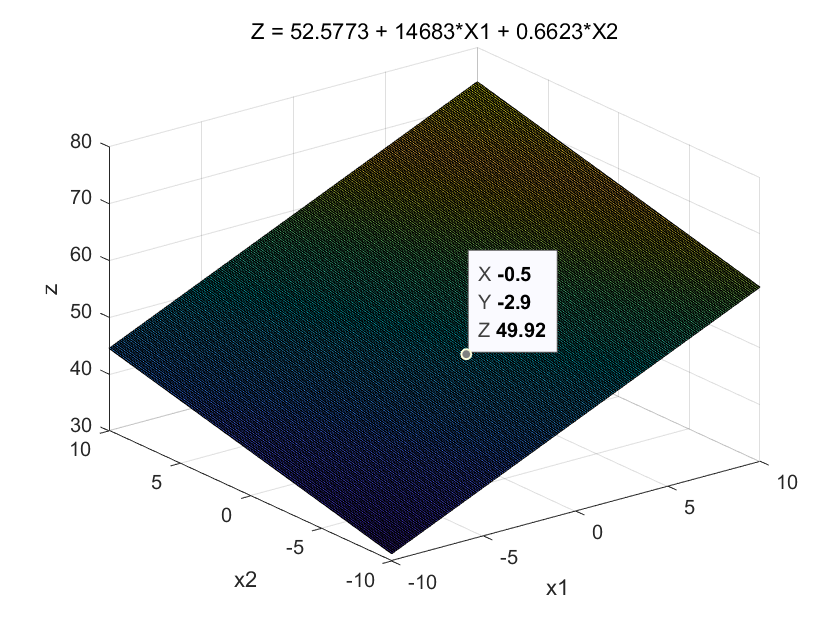


% 绘制三维图形
figure
surf(X1, X2, Z);
xlabel('x1');
ylabel('x2');
zlabel('z');
title('Z = 52.5773 + 14683*X1 + 0.6623*X2');